# MPC tuning with Bayesian Optimization

clc
clf
clear all
close all
rng(0)

## Parallel computing

if isempty(gcp('nocreate'))
    cluster = parcluster('local');
    parpool(cluster, cluster.NumWorkers);
end
p = gcp();
fprintf('Using %d parallel workers', p.NumWorkers);

Using 8 parallel workers

## Define optimization variables

% lambda_z = optimizableVariable('lambda_z', [1e-4, 1e-2], 'Transform', 'log');
% lambda_o = optimizableVariable('lambda_o', [1e-3, 1e-1], 'Transform', 'log');
% lambda   = optimizableVariable('lambda'  , [1e-2, 1], 'Transform', 'log');

% lambda_z = optimizableVariable('lambda_z', [1e-4, 1e-2], 'Transform', 'log');
% lambda_o = optimizableVariable('lambda_o', [1e-4, 1e-2], 'Transform', 'log');
% lambda   = optimizableVariable('lambda'  , [1e-3, 1e-1], 'Transform', 'log');

lambda_z = optimizableVariable('lambda_z', [1e-5, 1e-1], 'Transform', 'log');
lambda_o = optimizableVariable('lambda_o', [1e-5, 1e-1], 'Transform', 'log');
lambda   = optimizableVariable('lambda'  , [1e-5, 1e-1], 'Transform', 'log');

optimization_variables = [lambda_z, lambda_o, lambda];

## Bayesian optimization

Copying objective function to workers...
Done copying objective function to workers.
|==============================================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |     lambda_z |     lambda_o |       lambda |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|==============================================================================================================================|
|    1 |       8 | Best   |     0.88489 |      59.364 |     0.88489 |     0.88489 |    0.0020592 |     0.015968 |   0.00069718 |
|    2 |       2 | Accept |      1.5685 |      60.403 |     0.88489 |      0.8849 |     0.030485 |     0.016514 |   3.0602e-05 |
|    3 |       2 | Accept |      1.7988 |      60.199 |     0.88489 |      0.8849 |   0.00077339 |    1.401e-05 |    0.0015023 |
|    4 |    

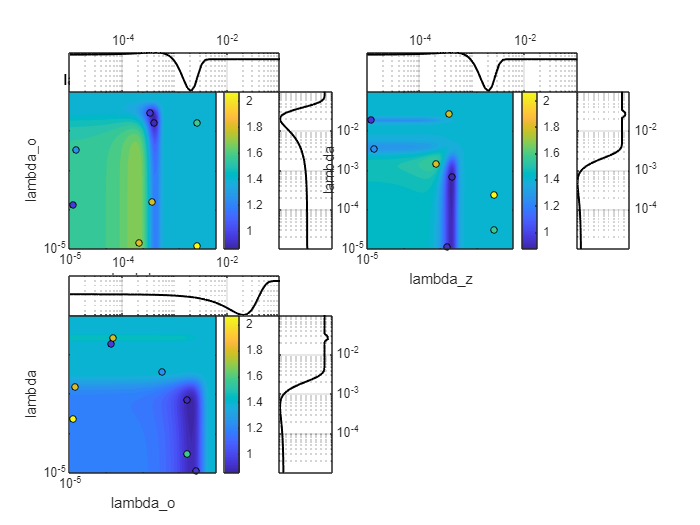

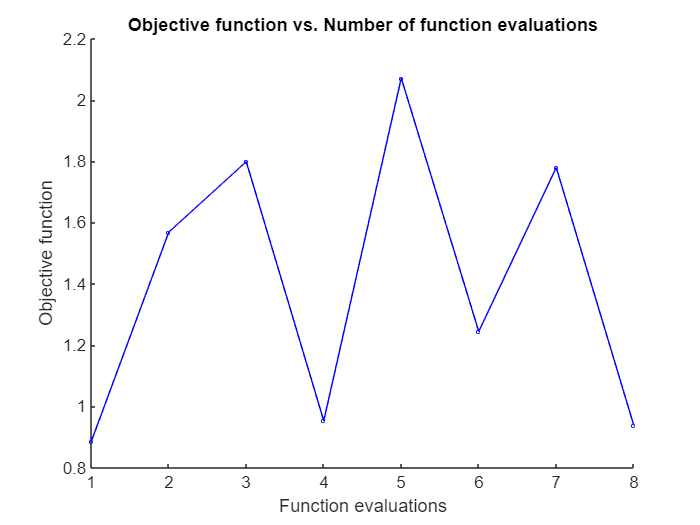

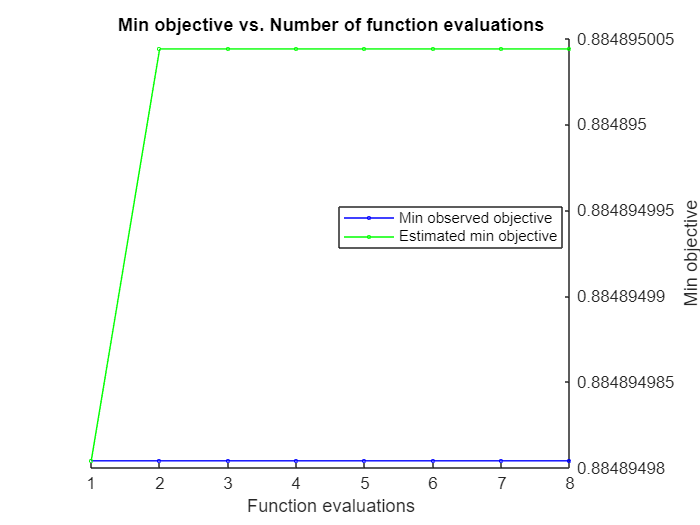

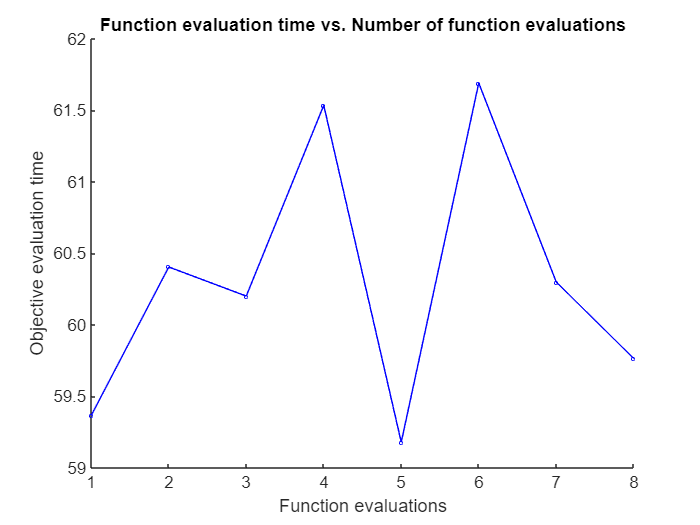

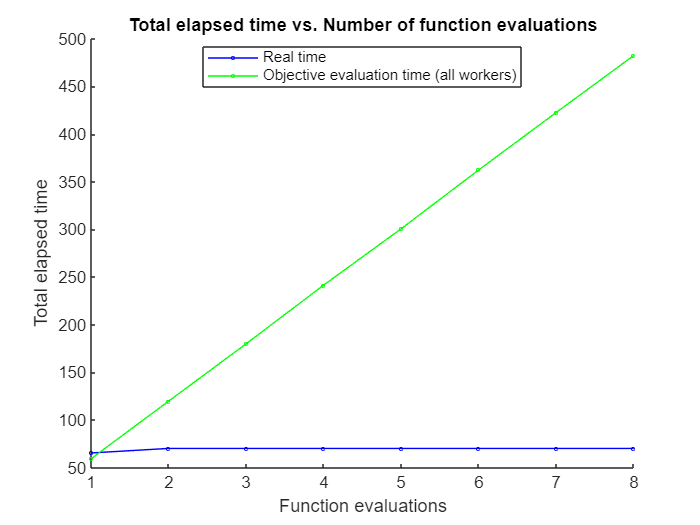

results = bayesopt(@objective_function, optimization_variables, ...
    'MaxObjectiveEvaluations',   100*p.NumWorkers, ...
    'NumSeedPoints',             2*p.NumWorkers, ...
    'AcquisitionFunctionName',   'expected-improvement-plus', ...
    'IsObjectiveDeterministic',  true, ...
    'UseParallel',               true, ...
    'Verbose',                   1, ...
    'PlotFcn', {@plotSurrogateSlice, @plotObjective, @plotMinObjective, @plotObjectiveEvaluationTime, @plotElapsedTime} ...
);

## Objective function

Simulate MMCC + Induction Machine and calculate MPC mean cost

function cost = objective_function(x)
    try
        cost = simulate(x);
    catch
        cost = 10;
    end
end

## Custom plot function

Plot surrogate model

% function stop = plotSurrogateSlice(results, state)
%     stop = false;
%     % Plot if an iteration is completed
%     if ~strcmp(state, 'iteration')
%         return;
%     end
%     % Optimization variables names
%     varsDesc = results.VariableDescriptions;
%     varNames = {varsDesc.Name};
%     numVar = numel(varNames);
%     % Fit gaussian process
%     gp = fitrgp(results.XTrace, results.ObjectiveTrace, 'Standardize', true, 'KernelFunction', 'ardsquaredexponential');
%     % Best estimated point
%     bestEst = table2struct(results.XAtMinEstimatedObjective);
%     % Observations
%     Xobs = results.XTrace;
%     Yobs = results.ObjectiveTrace;
%     % Update slices figure
%     figure(1);
%     clf;
%     for iVar = 1:numVar
%         % log scale range
%         lb = varsDesc(iVar).Range(1);
%         ub = varsDesc(iVar).Range(2);
%         xgrid = logspace(log10(lb), log10(ub), 200)';
%         % Construct prediction table for slice
%         Tpred = table();
%         for jVar = 1:numVar
%             nm = varNames{jVar};
%             if jVar == iVar
%                 Tpred.(nm) = xgrid;
%             else
%                 Tpred.(nm) = repmat(bestEst.(nm), numel(xgrid), 1);
%             end
%         end
%         % Predict mu and sigma
%         [mu, sigma] = predict(gp, Tpred);
%         % Subplot
%         subplot(numVar, 1, iVar);
%         hold on;
%         grid on;
%         % Confidence bound 95%
%         fill([xgrid; flipud(xgrid)], [mu+2*sigma; flipud(mu-2*sigma)], 0.9*[1 1 1], 'EdgeColor', 'none');
%         % Surrogate mean
%         plot(xgrid, mu, '-k', 'LineWidth', 1.5);
%         % Observated values
%         xi_obs = Xobs{:,iVar};
%         scatter(xi_obs, Yobs, 30, 'r', 'filled');
%         set(gca, 'XScale', 'log');
%         xlabel(varNames{iVar});
%         ylabel('Cost');
%         title(sprintf('Slice surrogate of %s', varNames{iVar}));
%     end
%     drawnow;
% end

% function stop = plotSurrogateSlice(results, state)
%     stop = false;
%     % Sólo al terminar cada iteración
%     if ~strcmp(state, 'iteration')
%         return;
%     end
% 
%     % Descripciones de variables
%     varsDesc = results.VariableDescriptions;
%     varNames = {varsDesc.Name};
%     D = numel(varNames);
% 
%     % Construye el modelo GP de las trazas acumuladas
%     gp = fitrgp(results.XTrace, results.ObjectiveTrace, ...
%                 'Standardize', true, ...
%                 'KernelFunction', 'ardsquaredexponential');
% 
%     % Punto de mínimo estimado
%     bestEst = table2struct(results.XAtMinEstimatedObjective);
% 
%     % Observaciones históricas
%     Xobs = results.XTrace;
%     Yobs = results.ObjectiveTrace;
% 
%     % Calcula cuadrícula de pares
%     pairs = nchoosek(1:D,2);
%     nPairs = size(pairs,1);
%     nCols  = ceil(sqrt(nPairs));
%     nRows  = ceil(nPairs/nCols);
% 
%     figure(2);
%     clf;
%     for k = 1:nPairs
%         iVar = pairs(k,1);
%         jVar = pairs(k,2);
% 
%         % Rango logarítmico de cada variable
%         lb_i = varsDesc(iVar).Range(1);
%         ub_i = varsDesc(iVar).Range(2);
%         lb_j = varsDesc(jVar).Range(1);
%         ub_j = varsDesc(jVar).Range(2);
% 
%         xi = logspace(log10(lb_i), log10(ub_i), 60);
%         xj = logspace(log10(lb_j), log10(ub_j), 60);
%         [Xi, Xj] = meshgrid(xi, xj);
% 
%         % Prepara tabla de predicción manteniendo resto fijo
%         Tpred = repmat(struct2table(bestEst), numel(Xi), 1);
%         Tpred.(varNames{iVar}) = Xi(:);
%         Tpred.(varNames{jVar}) = Xj(:);
% 
%         % Predice media
%         Mu = predict(gp, Tpred);
%         Mu = reshape(Mu, size(Xi));
% 
%         % Subplot
%         subplot(nRows, nCols, k);
%         contourf(Xi, Xj, Mu, 20, 'LineColor', 'none');
%         hold on;
%         % Puntos observados proyectados y coloreados por coste
%         scatter(Xobs{:,iVar}, Xobs{:,jVar}, 20, Yobs, 'filled', ...
%                 'MarkerEdgeColor','k');
%         set(gca, 'XScale','log', 'YScale','log');
%         xlabel(varNames{iVar}, 'Interpreter','none');
%         ylabel(varNames{jVar}, 'Interpreter','none');
%         title(sprintf('%s vs %s', varNames{iVar}, varNames{jVar}), ...
%               'Interpreter','none');
%         colorbar;
%         grid on;
%     end
% 
%     drawnow;
% end


function stop = plotSurrogateSlice(results, state)
    stop = false;
    % Sólo dibujar al completar cada iteración
    if ~strcmp(state, 'iteration')
        return;
    end

    % Descripciones de variables y datos
    varsDesc = results.VariableDescriptions;
    varNames = {varsDesc.Name};
    D        = numel(varNames);
    Xobs     = results.XTrace;
    Yobs     = results.ObjectiveTrace;
    bestEst  = table2struct(results.XAtMinEstimatedObjective);

    % Ajuste de Gaussian Process sobre todo lo observado
    gp = fitrgp(Xobs, Yobs, ...
        'Standardize', true, ...
        'KernelFunction', 'ardsquaredexponential');

    % Pares de variables a plotear
    pairs = nchoosek(1:D,2);
    nPairs = size(pairs,1);
    nCols  = ceil(sqrt(nPairs));
    nRows  = ceil(nPairs/nCols);

    % Configuración de layout de la figura completa
    figure(10); clf;
    margin   = 0.1;        % margen alrededor de toda la figura
    spacing  = 0.05;       % espacio entre tiles
    sliceFr  = 0.2;        % fracción reservada para cada slice
    availW   = 1 - 2*margin - (nCols-1)*spacing;
    availH   = 1 - 2*margin - (nRows-1)*spacing;
    tileW    = availW / nCols;
    tileH    = availH / nRows;

    for k = 1:nPairs
        iVar = pairs(k,1);
        jVar = pairs(k,2);

        % Cálculo de la posición del tile [x y w h] en coordenadas normalizadas
        colIdx = mod(k-1,nCols);
        rowIdx = floor((k-1)/nCols);
        tileLeft   = margin + colIdx*(tileW + spacing);
        tileBottom = 1 - margin - (rowIdx+1)*tileH - rowIdx*spacing;
        tilePos    = [tileLeft, tileBottom, tileW, tileH];

        % División interna: central vs slices
        mainPos  = [tilePos(1),                    tilePos(2),                     tilePos(3)*(1-sliceFr),         tilePos(4)*(1-sliceFr)];
        topPos   = [tilePos(1),                    tilePos(2)+tilePos(4)*(1-sliceFr), tilePos(3)*(1-sliceFr),         tilePos(4)*sliceFr];
        rightPos = [tilePos(1)+tilePos(3)*(1-sliceFr), tilePos(2),                     tilePos(3)*sliceFr,             tilePos(4)*(1-sliceFr)];

        % Rango log de cada variable
        lb_i = varsDesc(iVar).Range(1); ub_i = varsDesc(iVar).Range(2);
        lb_j = varsDesc(jVar).Range(1); ub_j = varsDesc(jVar).Range(2);
        xi   = logspace(log10(lb_i), log10(ub_i), 60);
        xj   = logspace(log10(lb_j), log10(ub_j), 60);
        [Xi, Xj] = meshgrid(xi, xj);

        % Prepara tabla de predicción para el contorno
        Tcont = repmat(struct2table(bestEst), numel(Xi), 1);
        Tcont.(varNames{iVar}) = Xi(:);
        Tcont.(varNames{jVar}) = Xj(:);
        MuC = predict(gp, Tcont);
        MuC = reshape(MuC, size(Xi));

        %% 1) Contorno central
        axMain = axes('Position', mainPos);
        contourf(axMain, Xi, Xj, MuC, 20, 'LineColor','none');
        hold(axMain,'on');
        scatter(axMain, Xobs{:,iVar}, Xobs{:,jVar}, 15, Yobs, 'filled', 'MarkerEdgeColor','k');
        set(axMain, 'XScale','log', 'YScale','log');
        xlabel(axMain, varNames{iVar}, 'Interpreter','none');
        ylabel(axMain, varNames{jVar}, 'Interpreter','none');
        title(axMain, sprintf('%s vs %s', varNames{iVar}, varNames{jVar}), 'Interpreter','none');
        colorbar(axMain);
        grid(axMain,'on');

        %% 2) Slice para iVar (eje superior)
        % Predecimos mu variando xi, con xj fijo en mejor estimado
        Ttop = repmat(struct2table(bestEst), numel(xi), 1);
        Ttop.(varNames{iVar}) = xi(:);
        MuT = predict(gp, Ttop);

        axTop = axes('Position', topPos);
        plot(axTop, xi, MuT, '-k','LineWidth',1.2);
        set(axTop, 'XScale','log', 'XAxisLocation','top', 'YTick',[]);
        xlim(axTop, [lb_i ub_i]);
        ylabel(axTop,''); xlabel(axTop, '');
        grid(axTop,'on');

        %% 3) Slice para jVar (eje derecho)
        Tright = repmat(struct2table(bestEst), numel(xj), 1);
        Tright.(varNames{jVar}) = xj(:);
        MuR = predict(gp, Tright);

        axRight = axes('Position', rightPos);
        plot(axRight, MuR, xj, '-k','LineWidth',1.2);
        set(axRight, 'YScale','log', 'YAxisLocation','right', 'XTick',[]);
        ylim(axRight, [lb_j ub_j]);
        xlabel(axRight,''); ylabel(axRight,'');
        grid(axRight,'on');
    end

    drawnow;
end
